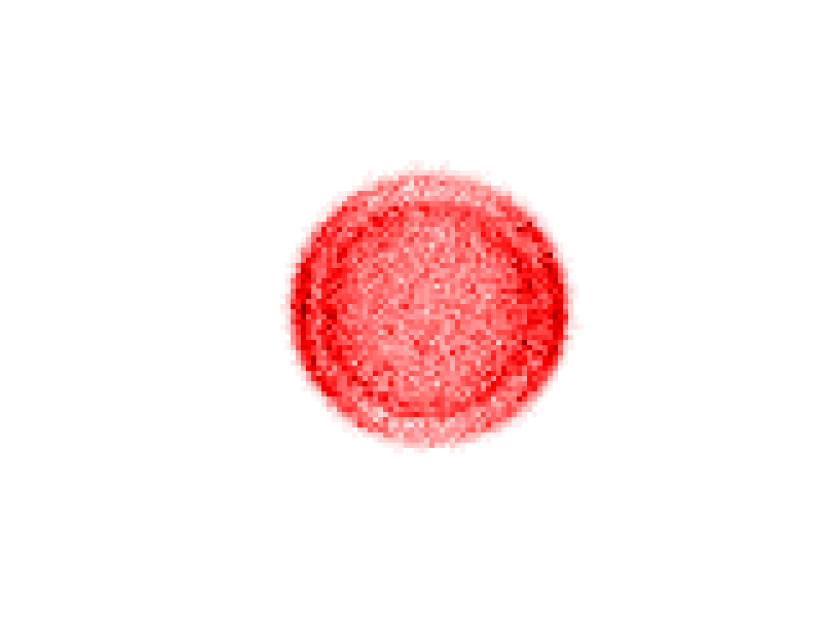

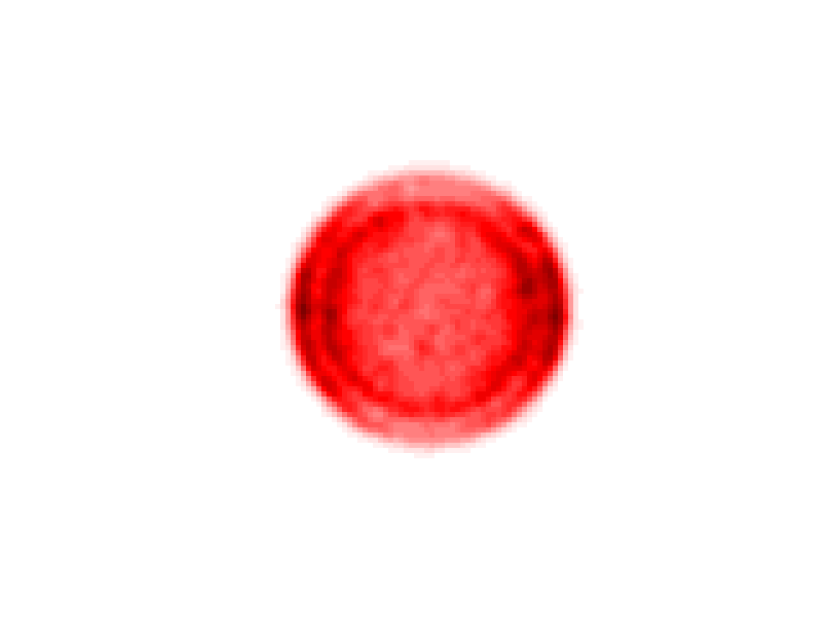

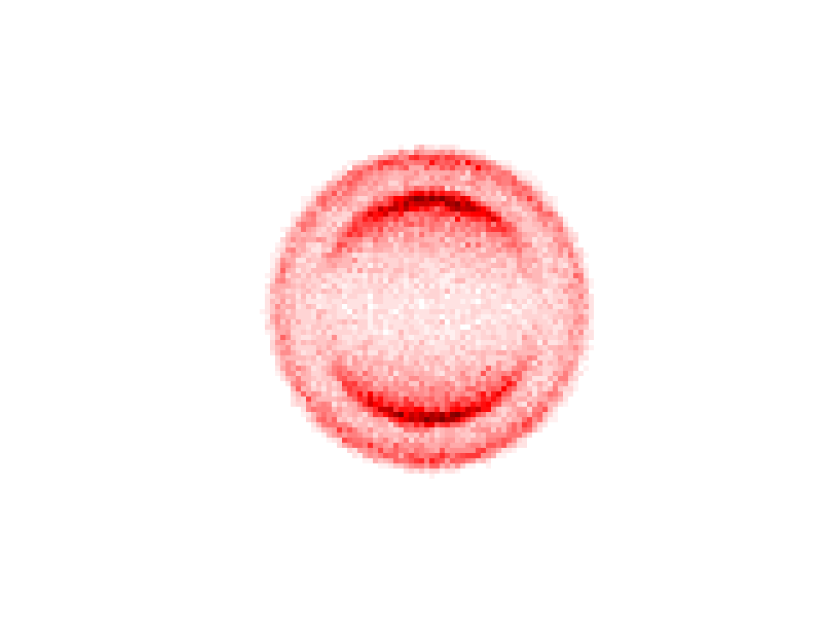

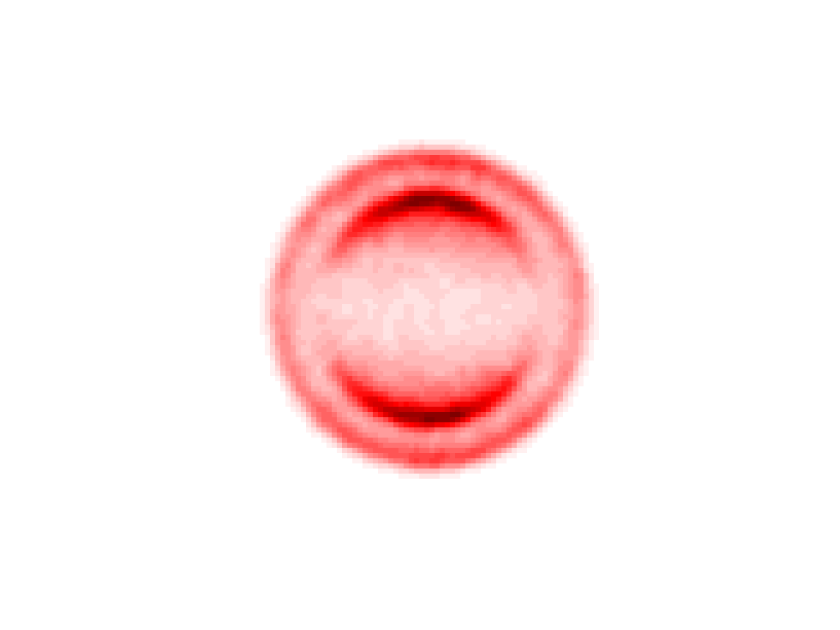

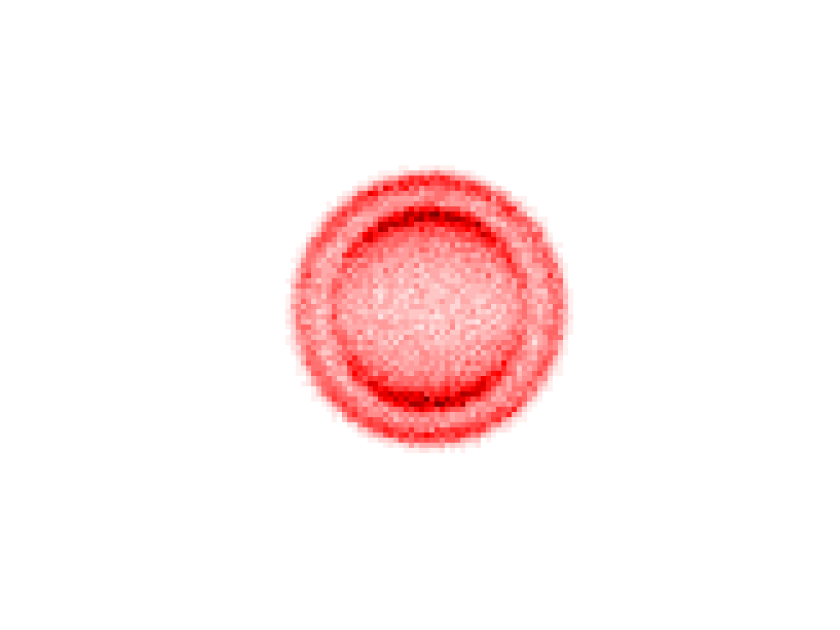

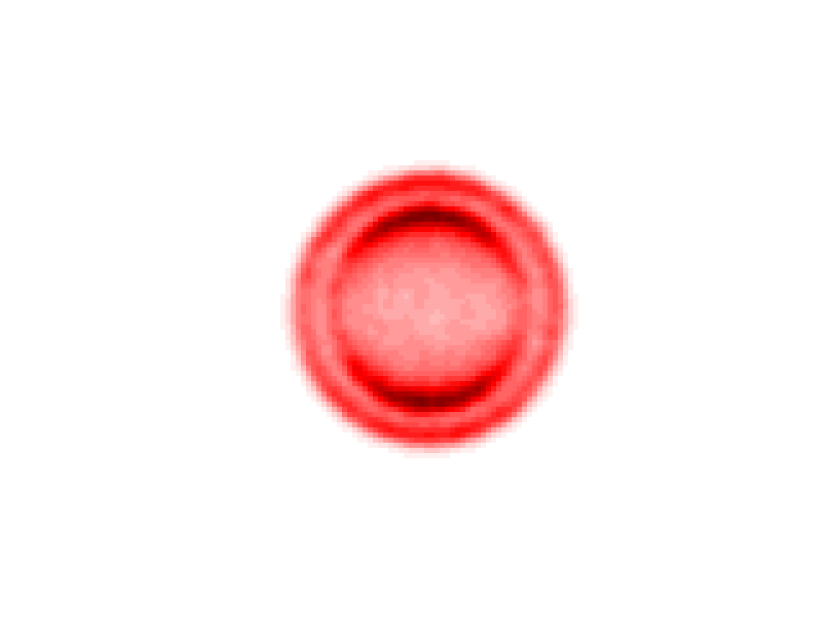

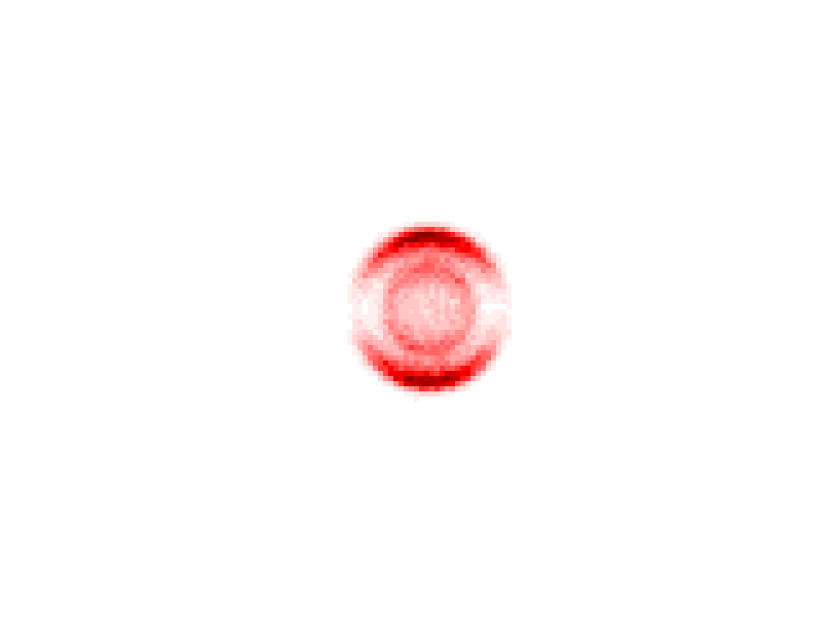

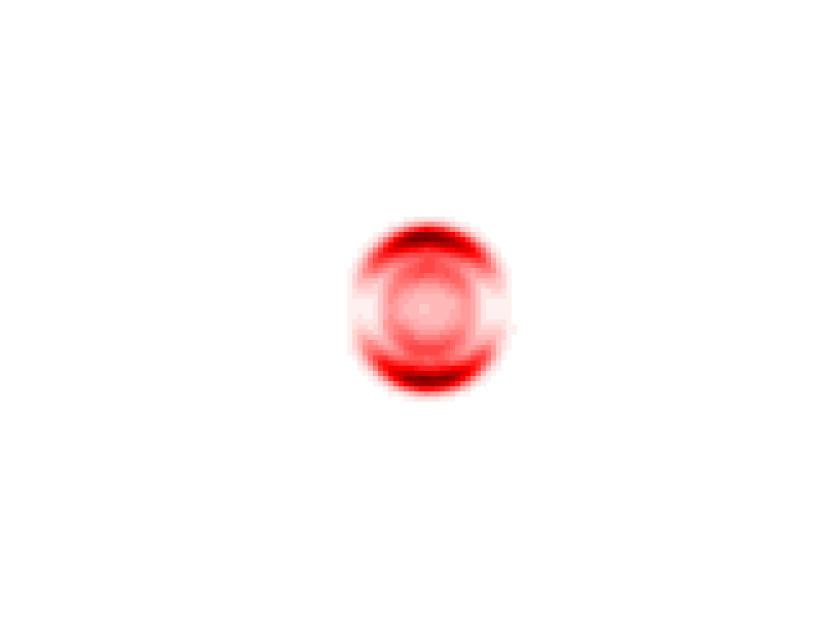

% This script was used to generate different randomised images governed by
% a set of experimentally realistic values.

% MPhys Research Project 2022/23
% Ross Anderson (H00295702)



% clear commands
clc
clear
close all


% set up coordinate system
x_res = 96;
y_res = 96;
x = linspace(-1, 1, x_res);
y = linspace(-1, 1, y_res);
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);

cos_theta = Y./R;

P2 = (1/2)*(3*cos_theta.^2 - 1);    %second legendre polynomial
P4 = (1/8)*(35*cos_theta.^4 - 30*cos_theta.^2 + 3);     %fourth legendre polynomial
P6 = (1/16)*(231*cos_theta.^6 - 315*cos_theta.^4 - 105*cos_theta.^2 - 5);   %sixth legendre polynomial

threshold = 0.01;
N = 1500;

coeffs.threshold_for_discard = threshold;
coeffs.number_of_images = N;

ring1 = cell(1, N);
ring1{1, N} = [];

ring2 = cell(1, N);
ring2{1, N} = [];

% -----------------------------------------------------------------------------------------------

for i = 1:N

    check = 0;
    while check == 0

        %ring 1
        W1 = 0.03;  %keep constant for now
        R1 = (0.7-0.4)*rand + 0.3;
        A1 = (1-0.6)*rand + 0.6;
        B21 = 3*rand - 1;
        I1 = A1*exp(-((R-R1)/W1).^2).*(1 + B21*P2);
        I1 = Abel(I1);
        %         I1 = I1/max(I1, [], 'all');
        %         I1 = rescale(I1);

        %ring 2
        W2 = 0.03;
        R2 = R1 + (-1)^(round(rand))*(0.2-0.025)*rand;
        A2 = (A1-0.5)*rand + 0.5;
        B22 = 3*rand - 1;
        I2 = A2*exp(-((R-R2)/W2).^2).*(1 + B22*P2);
        I2 = Abel(I2);
        %         I2 = I2/max(I1, [], 'all');
        %         I2 = rescale(I2);

        ring1{i} = I1;
        coeffs_ring1.W0(i) = W1;
        coeffs_ring1.R0(i) = R1;
        coeffs_ring1.B2(i) = B21;
        coeffs_ring1.A0(i) = A1;

        ring2{i} = I2;
        coeffs_ring2.W0(i) = W2;
        coeffs_ring2.R0(i) = R2;
        coeffs_ring2.B2(i) = B22;
        coeffs_ring2.A0(i) = A2;

        I_comb_check = I1 + I2;
        I_comb_check = I_comb_check/max(I_comb_check, [], 'all');

        if any(I_comb_check(1,:) > threshold) || any(I_comb_check(:,1) > threshold) || any(I_comb_check(end,:) > threshold) || any(I_comb_check(:,end) > threshold)
            check = 0;
        else
            check = 1;
        end

    end

end

ring1_mat = cell2mat(reshape(ring1, 1, 1, []));
ring2_mat = cell2mat(reshape(ring2, 1, 1, []));

images = cell(1, N);
images{1, N} = [];

images_sampled = cell(1, N);
images_sampled{1, N} = [];

images_gaussfilt = cell(1, N);
images_gaussfilt{1, N} = [];

%combined image
for i = 1:N
    I1 = ring1{i};
    I2 = ring2{i};
    I_combined = I1 + I2;
    I_combined = rescale(I_combined);
    %     showim(I_combined, 1)
    I_combined = I_combined/sum(I_combined, 'all');
    counts = rand*I_combined*10^5;
    I_sampled = poissrnd(counts, height(I_combined), length(I_combined));
    if sum(isnan(I_sampled)) > 0
        I_sampled = images_sampled{i - 1};
    end
    %     showim(I_sampled, 1)
    %     shading flat
    counts_in_image = sum(I_sampled,'all');
    coeffs.counts(i) = counts_in_image;
    I_gaussfilt = imgaussfilt(I_sampled, 1);    %changed from sigma = 2
    %     showim(I_gaussfilt, 1)
    %     shading flat
    I_combined = I_combined/max(I_combined, [], 'all');
    I_sampled = I_sampled/max(I_sampled, [], 'all');
    I_gaussfilt = I_gaussfilt/max(I_gaussfilt, [], 'all');
    images{i} = I_combined;
    images_sampled{i} = I_sampled;
    images_gaussfilt{i} = I_gaussfilt;
end

images_mat = cell2mat(reshape(images, 1, 1, []));
images_sampled_mat_full = cell2mat(reshape(images_sampled, 1, 1, []));
images_gaussfilt_mat_full = cell2mat(reshape(images_gaussfilt, 1, 1, []));

% crop to size
images_sampled_mat = images_sampled_mat_full((x_res/2+1):end, (x_res/2+1):end, :);
images_gaussfilt_mat = images_gaussfilt_mat_full((x_res/2+1):end, (x_res/2+1):end, :);

coeffs.ring1 = coeffs_ring1;
coeffs.ring2 = coeffs_ring2;
% training.centroid = images_sampled_mat;
% training.gaussfilt = images_gaussfilt_mat;

save("centroid", "images_sampled_mat")
save("gaussfilt", "images_gaussfilt_mat")
save("images", "images_mat")
save("coeffs", "coeffs")

for n = 1:5
    showim(images_sampled_mat_full(:, :, n), 1)
    shading flat
    showim(images_gaussfilt_mat_full(:, :, n), 1)
    shading flat
end


% for n = 1:10
%     % show simulated abel transformed images
%     showim(images_mat(:, :, n), 1)
%     title(n)

%     % show inverse abel and velocity dist
%     inverted_images_mat = InvAbel(images_mat(:, :, n));
%     showim(inverted_images_mat, 1)
%     title("" + n + "- Inverted")
%     [integrated_image, interp_integrated_image, radii, radii_whole]   = integrateim(inverted_images_mat);
%     interp_integrated_image = interp_integrated_image/max(interp_integrated_image);
%     figure()
%     plot(radii, interp_integrated_image)
%     title("" + n + " - Velocity distribution")
%     xlim([0, max(radii)])
%     ylim([0, 1.1])
%     xlabel("Radius (pixels)")
%     ylabel("Integrated signal (arb.)")


%     % show inverse abel blurred and velocity dist
%     inverted_blurred = InvAbel(images_gaussfilt_mat_full(:, :, n));
%     showim(inverted_blurred, 1)
%     title(n)
%     [integrated_blurred, interp_integrated_blurred, radii, radii_whole] = integrateim(inverted_blurred);
%     interp_integrated_blurred = interp_integrated_blurred/max(interp_integrated_blurred);
%     figure()
%     plot(radii, interp_integrated_blurred)
%     title("" + n + " - Velocity distribution")
%     xlim([0, max(radii)])
%     ylim([0, 1.1])
%     xlabel("Radius (pixels)")
%     ylabel("Integrated signal (arb.)")
%
%
%     %show inverse abel centroided and velocity dist
%     inverted_centroid = InvAbel (images_sampled_mat_full(:, :, n));
%     showim(inverted_centroid, 1)
%     title(n)
%     [integrated_centroid, interp_integrated_centroid, radii, radii_whole] = integrateim(inverted_centroid);
%     interp_integrated_centroid = interp_integrated_centroid/max(interp_integrated_centroid);
%     figure()
%     plot(radii, interp_integrated_centroid)
%     title("" + n + " - Velocity distribution")
%     xlim([0, max(radii)])
%     ylim([0, 1.1])
%     xlabel("Radius (pixels)")
%     ylabel("Integrated signal (arb.)")
%
%
% end



% % bias the validation data
% 
% val_gaussfilt = zeros(48, 48, 10);
% val_gaussfilt(:, :, 1) = images_gaussfilt_mat(:, :, 1);
% val_gaussfilt(:, :, 2) = images_gaussfilt_mat(:, :, 2);
% val_gaussfilt(:, :, 3) = images_gaussfilt_mat(:, :, 9);
% val_gaussfilt(:, :, 4) = images_gaussfilt_mat(:, :, 10);
% val_gaussfilt(:, :, 5) = images_gaussfilt_mat(:, :, 11);
% val_gaussfilt(:, :, 6) = images_gaussfilt_mat(:, :, 19);
% val_gaussfilt(:, :, 7) = images_gaussfilt_mat(:, :, 20);
% val_gaussfilt(:, :, 8) = images_gaussfilt_mat(:, :, 24);
% val_gaussfilt(:, :, 9) = images_gaussfilt_mat(:, :, 25);
% val_gaussfilt(:, :, 10) = images_gaussfilt_mat(:, :, 27);
% 
% val_sampled = zeros(48, 48, 10);
% val_sampled(:, :, 1) = images_sampled_mat(:, :, 1);
% val_sampled(:, :, 2) = images_sampled_mat(:, :, 2);
% val_sampled(:, :, 3) = images_sampled_mat(:, :, 9);
% val_sampled(:, :, 4) = images_sampled_mat(:, :, 10);
% val_sampled(:, :, 5) = images_sampled_mat(:, :, 11);
% val_sampled(:, :, 6) = images_sampled_mat(:, :, 19);
% val_sampled(:, :, 7) = images_sampled_mat(:, :, 20);
% val_sampled(:, :, 8) = images_sampled_mat(:, :, 24);
% val_sampled(:, :, 9) = images_sampled_mat(:, :, 25);
% val_sampled(:, :, 10) = images_sampled_mat(:, :, 27);
% 
% save("val_gaussfilt", "val_gaussfilt")
% save("val_sampled", "val_sampled")



% % add the validation data to the start of new data
% load("C:\Users\nlhdr\OneDrive - Heriot-Watt University\MPhys Physics\Year 5\Semester 1\Research Project\val_sampled.mat")
% load("C:\Users\nlhdr\OneDrive - Heriot-Watt University\MPhys Physics\Year 5\Semester 1\Research Project\val_gaussfilt.mat")
% 
% images_sampled_mat(:, :, 1:10) = val_sampled(:, :, 1:10);
% images_gaussfilt_mat(:, :, 1:10) = val_gaussfilt(:, :, 1:10);
% 
% save("centroid", "images_sampled_mat")
% save("gaussfilt", "images_gaussfilt_mat")

% single_image(:, :, 1) = images_sampled_mat(:, :, 4);
% single_image_blur(:, :, 1) = images_gaussfilt_mat(:, :, 4);
%
% single_image(:, :, 2) = images_sampled_mat(:, :, 4);
% single_image_blur(:, :, 2) = images_gaussfilt_mat(:, :, 4);
%
%
% save("centroid_single_image", "single_image")
% save("gaussfilt_single_image", "single_image_blur")



